# Fitting 2AFC, or change detection data

Except for the continuous report data, two-alternative forced-choice tasks are also supported by Memtoolbox For example, 3 item in 3 locations with 3 colors, 1 location cued, asked to pick which of the two colors the item at cued location was. To make use of such data, we can specify data.changeSize and data.afcCorrect rather than data.errors. data.changeSize indicates the difference between the 2 test items, in degrees; data.afcCorrect indicates whether the observer got the trial correct (1) or incorrect (0). 


Mean percent correct: 0.75
          Model:   2AFC Standard mixture model
     Parameters:   g, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.27
   ... not yet converged (400); btw/within variance: 1.50
   ... not yet converged (600); btw/within variance: 1.17
   ... chains converged after 800 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
       g	       0.006	   0.008	   0.833
      sd	      32.111	   8.488	  96.915



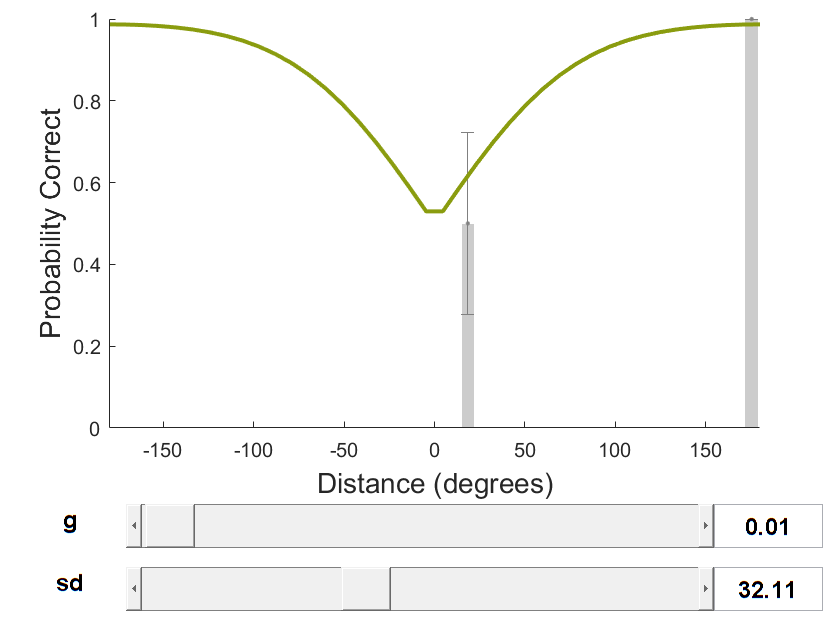

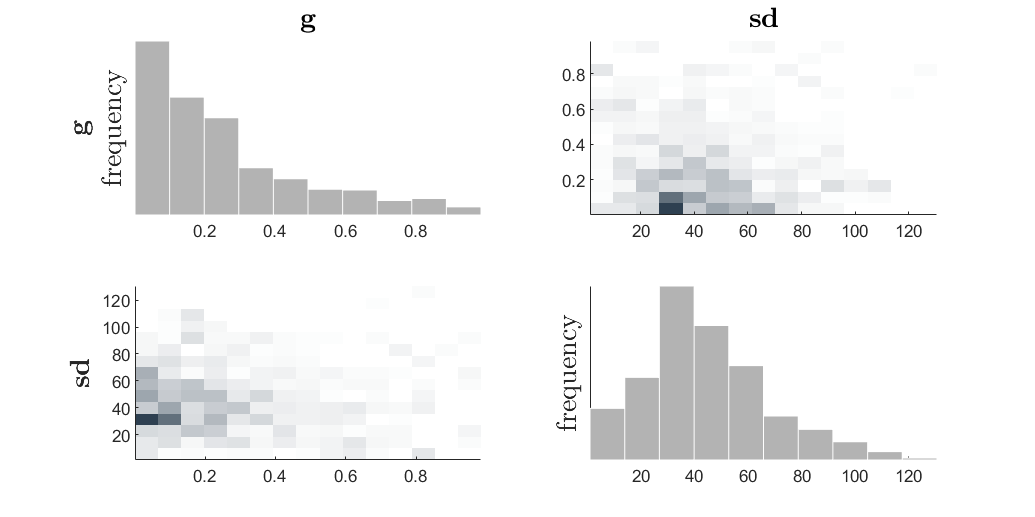

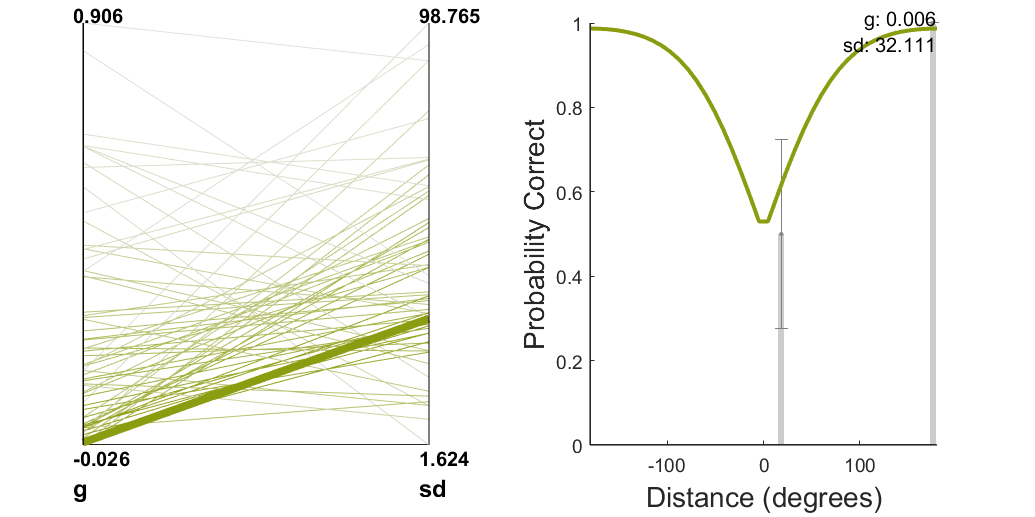

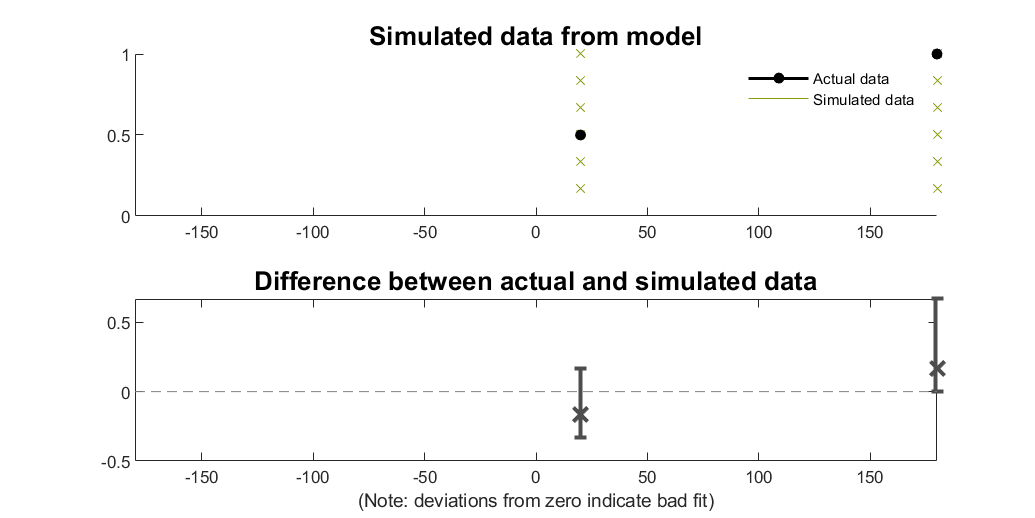


This analysis was performed using MemToolbox version 1.0.0.



clear all;
data.changeSize = [180 180 180 180 180 180 20 20 20 20 20 20];
data.afcCorrect = [1 1 1 1 1 1 0 0 0 1 1 1];

% we sometimes test observers with a very distant color (exactly the opposite 
% side of the color wheel), and observers get 100% of these trials correct; 
% and we sometimes test observers with a relatively close color (20 degrees 
% away on the color wheel), and observers get exactly 50% of those trials correct:

MemFit(data);

## TwoAFC() warpper function

The MemToolbox supports converting any model to a 2AFC model using the TwoAFC() wrapper function. Thus, to make a model for a 2AFC task with a SwapModel, you could use TwoAFC(SwapModel) as your model. However, for models that depend on information about particular displays (like the swap model), the 2AFC wrapper is somewhat slow, since it must compute the likelihood for each display separately.

Model=TwoAFC(SwapModel)

Model = struct with fields:
                    name: '2AFC Swap model'
              paramNames: {'g'  'B'  'sd'}
              lowerbound: [0 0 0]
              upperbound: [1 1 Inf]
                 movestd: [0.0200 0.0200 0.1000]
                     pdf: @TwoAFC/NewPDF
               modelPlot: @SwapModel/model_plot
               generator: @TwoAFC/NewGenerator
                   start: [3×3 double]
    requiresSeparateCDFs: 1
                isTwoAFC: 1
                  oldPdf: @SwapModelPDF
              interpVals: [1×1000 double]
